%тест1
format long;
n = 15;
H = hilb(n);
e = ones(n,1);
b = H*e;
x_lu = LUsolver(H,b);
x_qr = QRsolver(H,b);
norm(x_lu - e)

ans =   33.263291580810503


norm(x_qr - e)

ans =   28.899290842958582


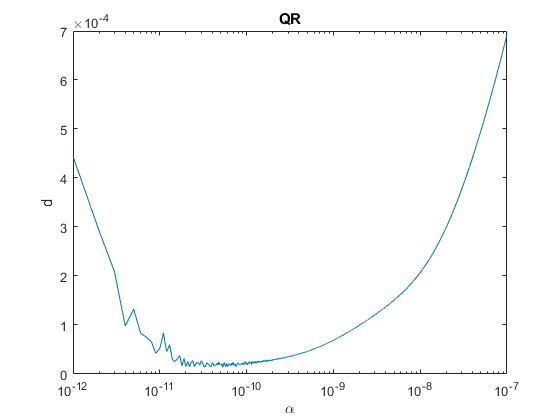

alpha = 1e-12;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = QRsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('QR');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      5.300000000000000e-11


disp('Который равен:');

Который равен:


m

m =      1.379519801580031e-05


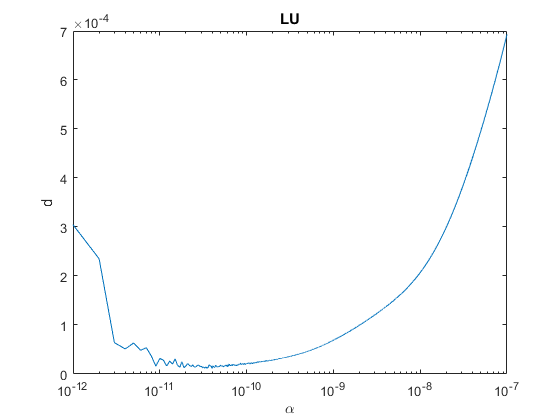

alpha = 1e-12;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = LUsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('LU');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      4.000000000000000e-11


disp('Который равен:');

Который равен:


m

m =      1.134933678514576e-05


%тест2
n = 20;
H = hilb(n);
e = ones(n,1);
b = H*e;
x_lu = LUsolver(H,b);
x_qr = QRsolver(H,b);
norm(x_lu - e)

ans =      1.098809081399329e+02


norm(x_qr - e)

ans =      8.202254306953326e+02


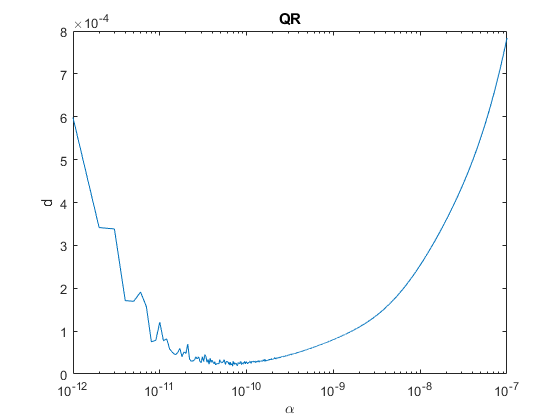

alpha = 1e-12;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = QRsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('QR');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      6.899999999999999e-11


disp('Который равен:');

Который равен:


m

m =      1.811892049039524e-05


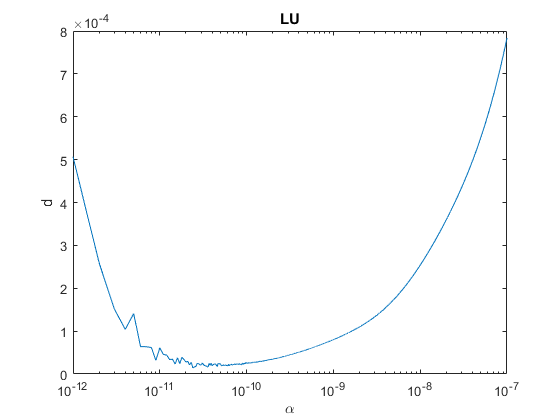

alpha = 1e-12;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = LUsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('LU');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      2.400000000000000e-11


disp('Который равен:');

Который равен:


m

m =      1.426026695365296e-05


%тест3
n = 25;
H = hilb(n);
e = ones(n,1);
b = H*e;
x_lu = LUsolver(H,b);
x_qr = QRsolver(H,b);
norm(x_lu - e)

ans =      1.373505501433260e+02


norm(x_qr - e)

ans =      1.150728211161796e+03


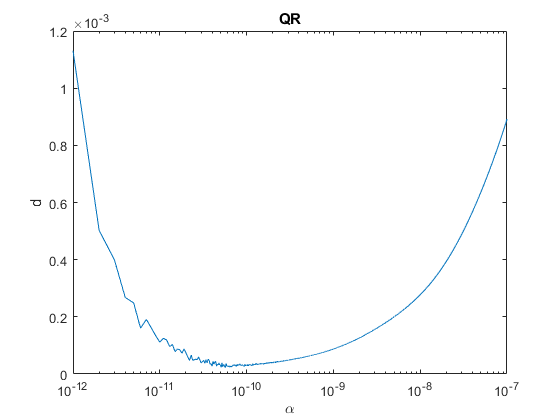

alpha = 1e-12;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = QRsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('QR');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      5.700000000000000e-11


disp('Который равен:');

Который равен:


m

m =      2.284509346695816e-05


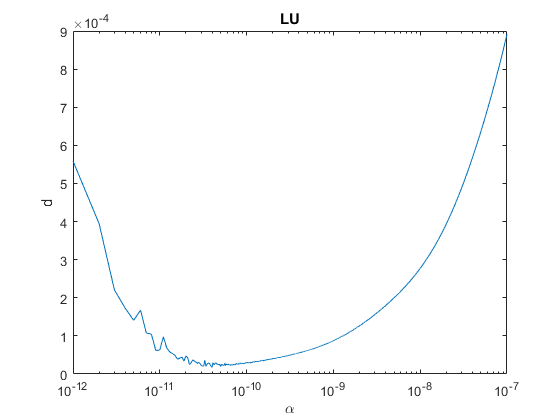

alpha = 1e-12;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = LUsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('LU');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      4.000000000000000e-11


disp('Который равен:');

Который равен:


m

m =      1.772026953127002e-05
